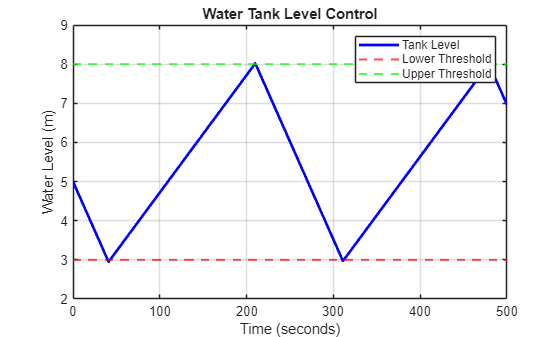

% Author: Christopher Bourjaili
% Module 2
% Project 17
% Title: Water Tank Level Control
%
% Summary of Code:
% - Simulates water level changes inside a storage tank over time.
% - Models tank inflow and outflow rates.
% - Uses upper and lower thresholds to control pump filling behavior.
% - Updates water level using time-stepped logic.
% - Creates a plot of tank level with threshold markers.
% - Demonstrates steady-state oscillation caused by on/off control.
%
% What I Learned:
% This project demonstrated how MATLAB can model control systems using
% loops, conditions, and dynamic balance equations. I learned that simple
% threshold controllers can maintain acceptable operating levels, but they
% often create repeated oscillations between limits. I also practiced
% analyzing system stability and how inflow/outflow rates affect behavior.

clc
clear
close all

dt = 1;                     
t_total = 500;              

t = 0:dt:t_total;
n = length(t);

level_max = 10;             
level_min = 3;              
level_high = 8;             

inflow_rate = 0.08;         
outflow_rate = 0.05;        

level = zeros(1,n);
pump_on = zeros(1,n);

level(1) = 5;

for i = 2:n
    
    if level(i-1) <= level_min
        pump_on(i) = 1;
    elseif level(i-1) >= level_high
        pump_on(i) = 0;
    else
        pump_on(i) = pump_on(i-1);
    end

    net_flow = pump_on(i)*inflow_rate - outflow_rate;

    level(i) = level(i-1) + net_flow*dt;

    if level(i) > level_max
        level(i) = level_max;
    elseif level(i) < 0
        level(i) = 0;
    end
    
end

figure
plot(t, level,'b','LineWidth',2)
hold on
yline(level_min,'r--','LineWidth',1.5)
yline(level_high,'g--','LineWidth',1.5)
grid on

xlabel('Time (seconds)')
ylabel('Water Level (m)')
title('Water Tank Level Control')
legend('Tank Level','Lower Threshold','Upper Threshold')


disp('Control Logic and Stability:')

Control Logic and Stability:


disp('1. Pump turns ON when level falls to lower threshold.')

1. Pump turns ON when level falls to lower threshold.


disp('2. Pump turns OFF when level reaches upper threshold.')

2. Pump turns OFF when level reaches upper threshold.


disp('3. Outflow continuously drains the tank.')

3. Outflow continuously drains the tank.


disp('4. System produces repeating level oscillations between limits.')

4. System produces repeating level oscillations between limits.


disp('5. Threshold spacing influences stability and switching frequency.')

5. Threshold spacing influences stability and switching frequency.
